outdir = "./output/jobs/allrisk_base_pairwise";
rawdir = fullfile(outdir, "raw/chunk_1");

accent = "surplus";
invest_cat = "advance_capacity";
all_cats = {'advance_capacity', 'improved_early_warning', ...
            'neglected_pathogen_rd', 'universal_flu_rd'};
accents = {'bcr", "surplus'};

all_files = struct2table(dir(rawdir));
all_files = all_files(~contains(all_files.name, "_prevac"), :);
all_files = all_files(~contains(all_files.name, "_prec1"), :);
all_files.fp = fullfile(all_files.folder, all_files.name);
all_files = all_files(:, {'name', 'fp'});

% Add scenario categories
for i = 1:length(all_cats)
    all_files.(all_cats{i}) = contains(all_files.name, all_cats{i});
end

surplus_files = all_files(contains(all_files.name, 'surplus'), :);
rel_sum_files = surplus_files(contains(surplus_files.name, "_relative_sums.mat"), :);
p_table_files = surplus_files(contains(surplus_files.name, "_pandemic_table"), :);

[compl_raw, compl_perc, pos_sample, neg_sample] = get_complementarity_vec("advance_capacity", "improved_early_warning", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
histogram(compl_perc, 'Normalization', 'probability');

I understand why advance capacity and improved early warning can be both complements and substitutes, depending on order of true and false positives.

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("advance_capacity", "neglected_pathogen_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);

mean(compl_perc)

ans = 0.0679

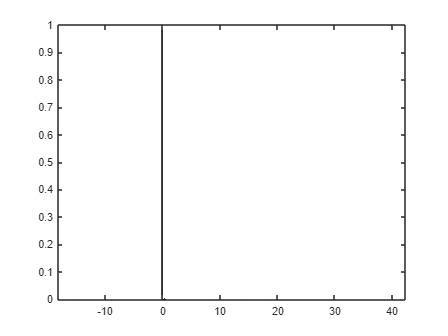

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("advance_capacity", "universal_flu_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[adv_cap_p_table, univ_flu_p_table] = load_pand_tables("advance_capacity", "universal_flu_rd", p_table_files, all_cats)

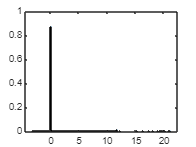

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("improved_early_warning", "universal_flu_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[early_warn_p_table, univ_flu_p_table] = load_pand_tables("improved_early_warning", "universal_flu_rd", p_table_files, all_cats);

early_warn_p_table = 747156×34 table
    sim_num    yr_start    is_false                pathogen                 early_detection_q    intensity    actual_dur    eff_severity    universal_flu_vaccine_state    crimean_congo_hemorrhagic_fever_prototype_state    lassa_prototype_state    rift_valley_fever_prototype_state    month_response_vaccine_ready    prep_start_month    response_initiated    has_prototype    has_adv_prototype    prototype_acquired_from_response    ufv_protection     rd_state_desc     cap_avail_m    cap_avail_o     m_deaths     vax_benefits    m_mortality_losses

univ_flu_p_table = 230027×34 table
    sim_num    yr_start    is_false                pathogen                 early_detection_q    intensity    actual_dur    eff_severity    universal_flu_vaccine_state    crimean_congo_hemorrhagic_fever_prototype_state    lassa_prototype_state    rift_valley_fever_prototype_state    month_response_vaccine_ready    prep_start_month    response_initiated    has_prototype    has_adv_prototype    prototype_acquired_from_response    ufv_protection     rd_state_desc     cap_avail_m    cap_avail_o     m_deaths     vax_benefits    m_mortality_losses</

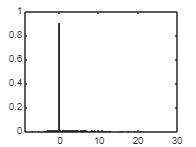

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("improved_early_warning", "neglected_pathogen_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[early_warn_p_table, neglect_rd_p_table] = load_pand_tables("improved_early_warning", "neglected_pathogen_rd", p_table_files, all_cats);

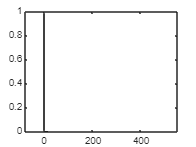

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

function [invest_one_p_table, invest_two_p_table] =  load_pand_tables(invest_one, invest_two, p_table_files, all_cats)

    invest_one_idx = contains(p_table_files.name, invest_one);
    invest_two_idx = contains(p_table_files.name, invest_two);
    alone_idx = table2array(sum(p_table_files(:, all_cats), 2) == 1);

    invest_one_p_table = load(char(p_table_files.fp(invest_one_idx & alone_idx)));
    invest_one_p_table = invest_one_p_table.pandemic_table;
    invest_two_p_table = load(char(p_table_files.fp(invest_two_idx & alone_idx)));
    invest_two_p_table = invest_two_p_table.pandemic_table;
end

function [compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec(...
    invest_one, invest_two, seed, results_files, p_table_files, all_cats)

    invest_one_idx = contains(results_files.name, invest_one);
    invest_two_idx = contains(results_files.name, invest_two);
    alone_idx = table2array(sum(results_files(:, all_cats), 2) == 1);

    invest_one_rel_sums = load(char(results_files.fp(invest_one_idx & alone_idx)));
    invest_two_rel_sums = load(char(results_files.fp(invest_two_idx & alone_idx)));
    combined_rel_sums = load(char(results_files.fp(invest_one_idx & invest_two_idx)));

    invest_one_benefits = invest_one_rel_sums.scenario_sum_table.benefits_vaccine_full;
    invest_two_benefits = invest_two_rel_sums.scenario_sum_table.benefits_vaccine_full;
    combined_rel_sums = combined_rel_sums.scenario_sum_table.benefits_vaccine_full;

    standalone_benefits_sum = invest_one_benefits + invest_two_benefits;
    compl_raw = combined_rel_sums - standalone_benefits_sum;
    compl_perc = 100 * compl_raw ./ (standalone_benefits_sum + eps);

    combined_pandemic_table = load(char(p_table_files.fp(invest_one_idx & invest_two_idx)));
    combined_pandemic_table = combined_pandemic_table.pandemic_table;
    
    rng(seed);
    neg_idx = randsample(find(compl_perc < 0), 50, false);
    pos_idx = randsample(find(compl_perc > 0), 50, false);

    neg_sample = combined_pandemic_table(ismember(combined_pandemic_table.sim_num, neg_idx), :);
    pos_sample = combined_pandemic_table(ismember(combined_pandemic_table.sim_num, pos_idx), :);
end